% Esta com a minha pasta mas n sei se podemos entregar assim
caminho_pasta = 'C:\Users\diogo\OneDrive\Documentos\Ficheiros\DEI\2_ANO\2_SEMESTRE\ATD\data\36\';

% Vai buscar todos os arquivos audio
arquivos = dir([caminho_pasta, '*.wav']);


matriz_audios=zeros(500,48000);
maior_audio=0;


for i = 1:length(arquivos)
    
    % vai buscar o nome do ficheiro e o caminho ate esse ficheiro
    caminho_arquivo = [caminho_pasta, arquivos(i).name];

    % le o ficheiro
    [audio, taxa_amostragem] = audioread(caminho_arquivo);

    matriz_audios(i,1:length(audio))=audio;

    if length(audio) > maior_audio
        maior_audio = length(audio);
    end

end
%RETIRAR SILENCIO INICIAL E NORMALIZAR AUDIO
matriz_audios_sem_silencio=zeros(500,maior_audio);
matriz_audios_normalizados=zeros(500,maior_audio);

for i = 1:length(arquivos)
    audio=matriz_audios(i, :);

    limiar_amplitude= 0.1 * max(abs(audio));
    indice_inicio = find(abs(audio) > limiar_amplitude, 1,'first');
    indice_fim = find(abs(audio) > limiar_amplitude, 1, 'last');
    
    audio_sem_silencio= audio(indice_inicio:indice_fim);
    matriz_audios_sem_silencio(i,1:length(audio_sem_silencio)) = audio_sem_silencio;
    

    %NORMALIZAR AUDIO
    maior_amplitude = max(abs(audio_sem_silencio));
    audio_normalizado = audio_sem_silencio / maior_amplitude;
    matriz_audios_normalizados(i,1:length(audio_normalizado))=audio_normalizado;
    

end
%Correr os audios e tentar adivinha os digitos

numeros_certos=0;
matriz_comparacao_resultados=zeros(length(arquivos),2);

for i = 1:length(arquivos)
    audio=matriz_audios_normalizados(i, :);

    numero_adivinhado=adivinha_numero(audio,taxa_amostragem);
    numero_dito = floor((i-1) / 50); % Determina o dígito esperado

    matriz_comparacao_resultados(i,1)=numero_dito;
    matriz_comparacao_resultados(i,2)=numero_adivinhado;

    if numero_adivinhado == numero_dito
        numeros_certos= numeros_certos+1;

    end


end

Perentagem_certos = (numeros_certos/length(arquivos))*100;
disp(Perentagem_certos);

   65.6000



disp(matriz_comparacao_resultados);

     0     0
     0     5
     0     7
     0     5
     0     5
     0     5
     0     0
     0     0
     0     7
     0     0
     0     0
     0     5
     0     0
     0     7
     0     0
     0     0
     0     0
     0     7
     0     5
     0     7
     0     0
     0     0
     0     0
     0     0
     0     5
     0     0
     0     0
     0     0
     0     0
     0     9
     0     0
     0     0
     0     0
     0     5
     0     0
     0     9
     0     0
     0     0
     0     5
     0     9
     0     0
     0     0
     0     0
     0     0
     0     0
     0     5
     0     9
     0     0
     0     0
     0     0
     1     3
     1     1
     1     1
     1     1
     1     8
     1     1
     1     3
     1     9
     1     9
     1     1
     1     1
     1     5
     1     9
     1     1
     1     9
     1     9
     1     1
     1     9
     1     1
     1     1
     1     5
     1     1
     1     3
     1     1
     1     1
     1     1
     1     1

%Plots
matriz_feature_1= zeros(length(arquivos),1);
matriz_feature_2=zeros(length(arquivos),1);
matriz_feature_3=zeros(length(arquivos),1);
matriz_feature_4=zeros(length(arquivos),1);
matriz_feature_5=zeros(length(arquivos),1);
matriz_feature_6=zeros(length(arquivos),1);
matriz_feature_7=zeros(length(arquivos),1);

audios_blackman=zeros(length(arquivos),maior_audio);
audios_hamming=zeros(length(arquivos),maior_audio);
audios_hanning=zeros(length(arquivos),maior_audio);

amplitude_spetrum = zeros(length(arquivos), length(matriz_audios_normalizados(1,:))/2 + 1);


for i = 1:length(arquivos)
    audio=matriz_audios_normalizados(i, :);

    matriz_feature_1(i)=feature1(audio,taxa_amostragem);
    matriz_feature_2(i)=feature2(audio,taxa_amostragem);
    matriz_feature_3(i)=feature3(audio,taxa_amostragem);
    matriz_feature_4(i)=feature4(audio,taxa_amostragem);
    matriz_feature_5(i)=feature5(audio,taxa_amostragem);
    matriz_feature_6(i)=feature6(audio,taxa_amostragem);
    matriz_feature_7(i)=feature7(audio);

    audios_blackman(i,:)=janela_blackman(audio);
    audios_hamming(i,:)=janela_hamming(audio);
    audios_hanning(i,:)=janela_hanning(audio);

    amplitude_spetrum(i,:)=calcular_fft(audio);

end

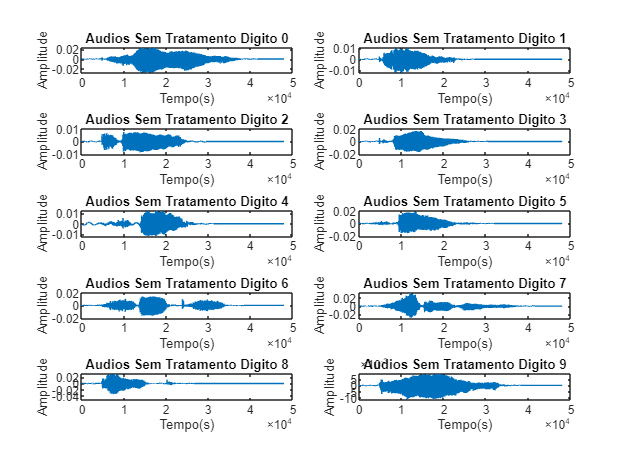

%plot audios iniciais e audios normalizados
plot_audios(matriz_audios,'Audios Sem Tratamento Digito ','Tempo(s)','Amplitude');

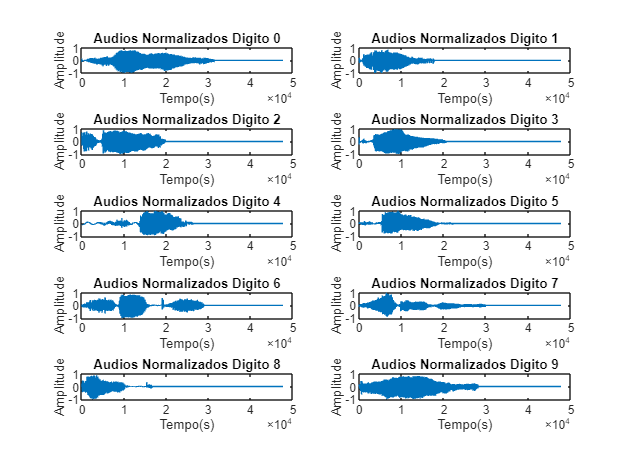

plot_audios(matriz_audios_normalizados,'Audios Normalizados Digito ','Tempo(s)','Amplitude');

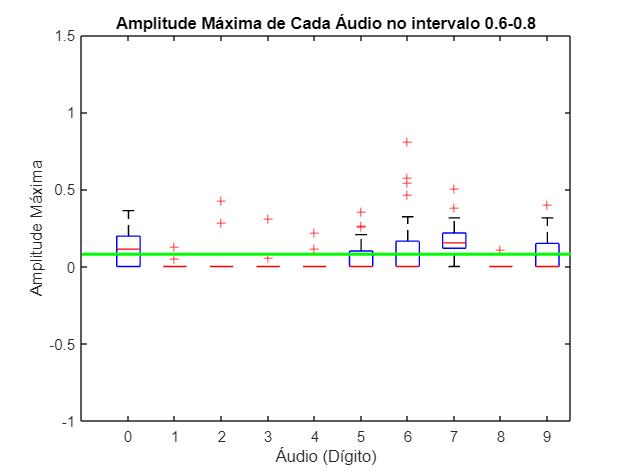

%plot das caracteristicas
plot_grafico(matriz_feature_1,0.08,'Amplitude Máxima de Cada Áudio no intervalo 0.6-0.8','Amplitude Máxima');

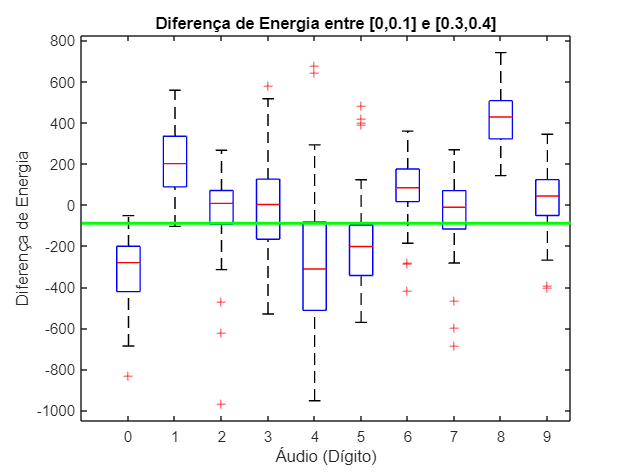

plot_grafico(matriz_feature_2,-90,'Diferença de Energia entre [0,0.1] e [0.3,0.4]','Diferença de Energia');

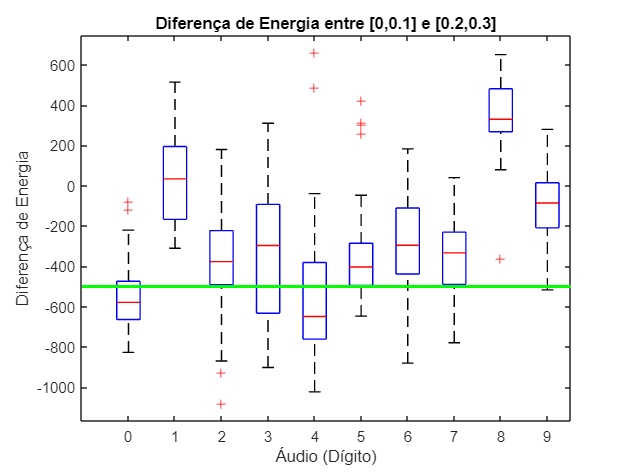

plot_grafico(matriz_feature_3,-500,'Diferença de Energia entre [0,0.1] e [0.2,0.3]','Diferença de Energia');

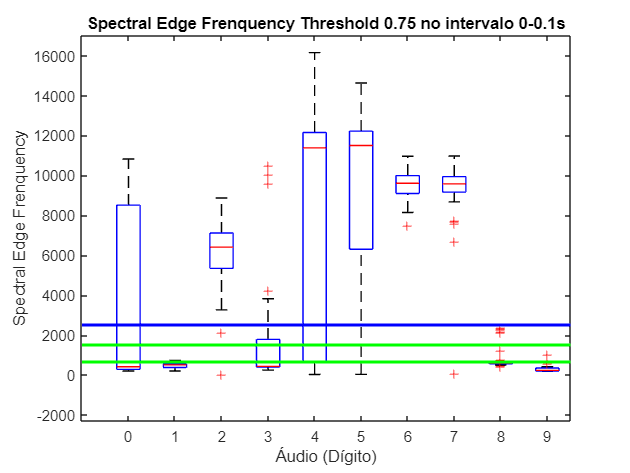

plot_grafico4(matriz_feature_4,650,1500,2500,'Spectral Edge Frenquency Threshold 0.75 no intervalo 0-0.1s','Spectral Edge Frenquency');

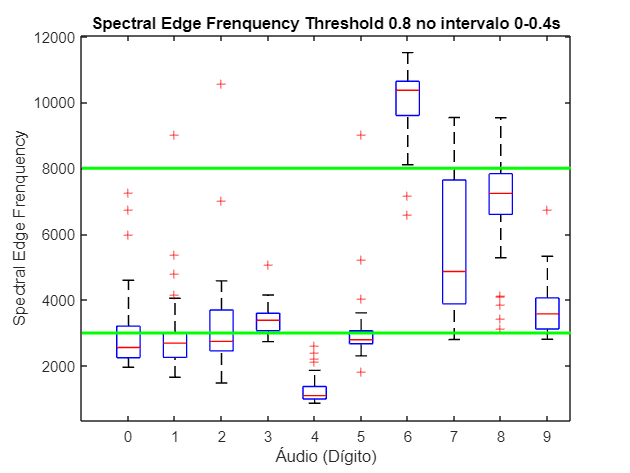

plot_grafico5(matriz_feature_5,8000,3000,'Spectral Edge Frenquency Threshold 0.8 no intervalo 0-0.4s','Spectral Edge Frenquency');

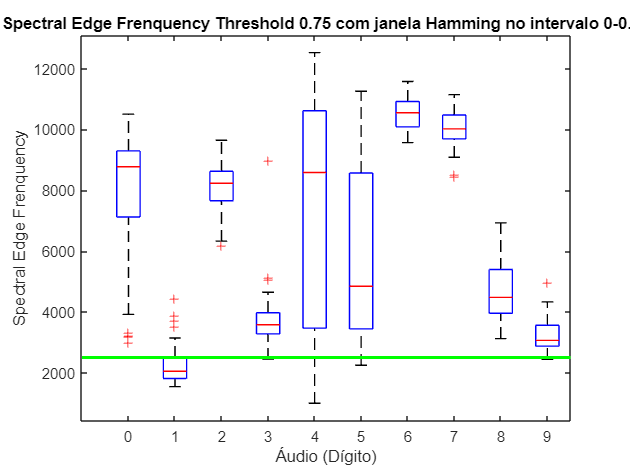

plot_grafico(matriz_feature_6,2500,'Spectral Edge Frenquency Threshold 0.75 com janela Hamming no intervalo 0-0.4s','Spectral Edge Frenquency');

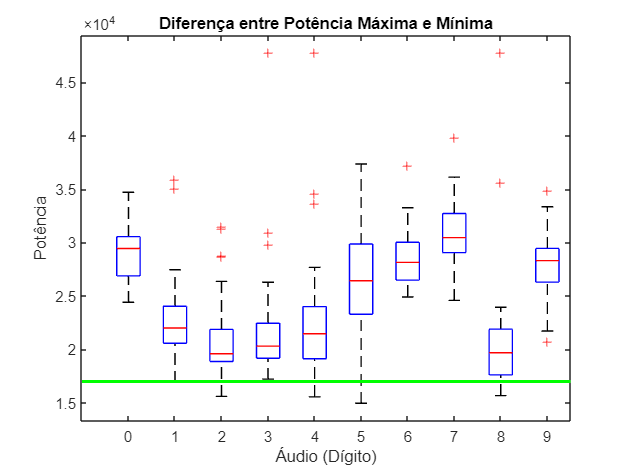

plot_grafico(matriz_feature_7,17000,'Diferença entre Potência Máxima e Mínima','Potência');

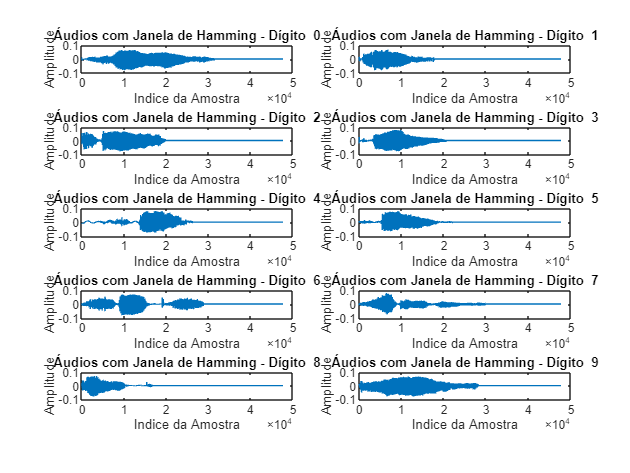

%plot das janelas
plot_audios(audios_hamming,'Áudios com Janela de Hamming - Dígito  ','Indice da Amostra','Amplitude');

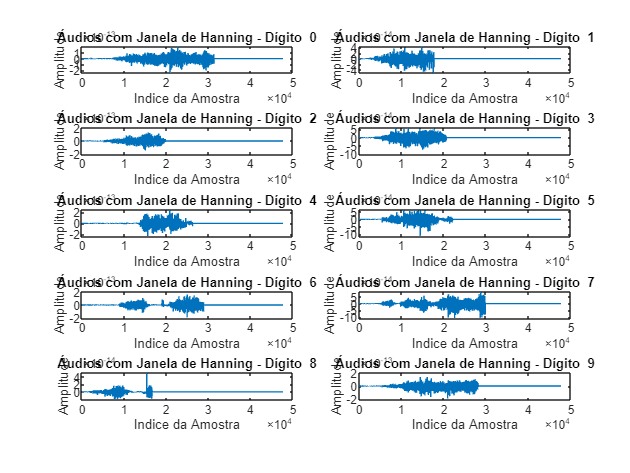

plot_audios(audios_hanning,'Áudios com Janela de Hanning - Dígito  ','Indice da Amostra','Amplitude');

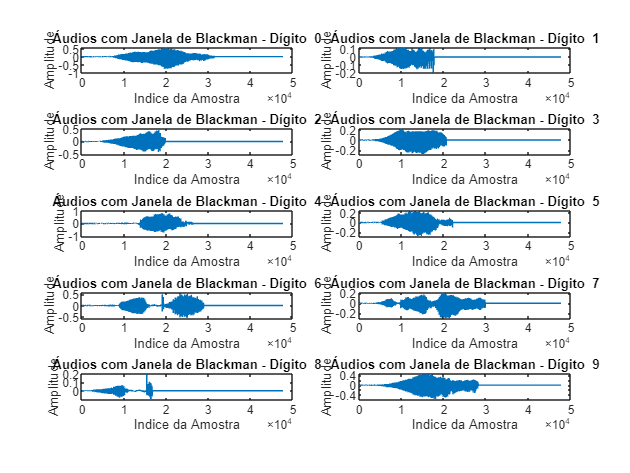

plot_audios(audios_blackman,'Áudios com Janela de Blackman - Dígito  ','Indice da Amostra','Amplitude');

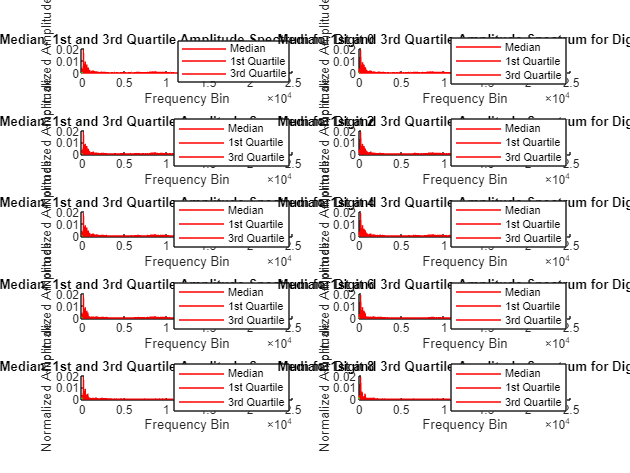

%outros plots pedidos no enunciado
plot_mediana_quartis(amplitude_spetrum,maior_audio);

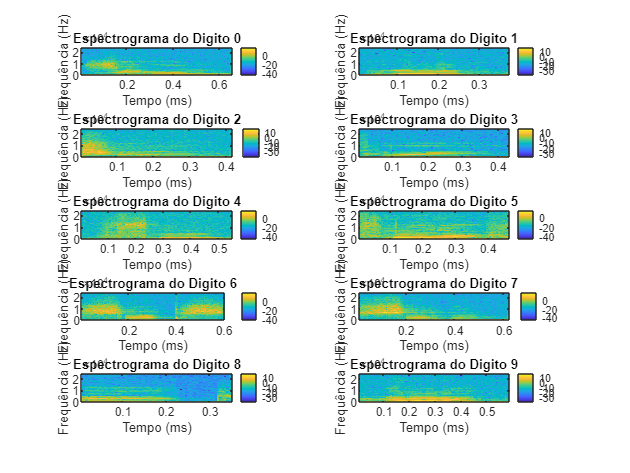

plot_STFT(matriz_audios_normalizados,taxa_amostragem);

function Adivinha= adivinha_numero(audio,taxa_amostragem)

    %passar o audio pelas caracteristicas
    %se calhar e melhor em vez de passar o audio passar o indice e vou so
    %buscar as matrizes pq ja fiz as caracteristicas antes
    limiar_1 = feature1(audio,taxa_amostragem);
    limiar_2=feature2(audio,taxa_amostragem);
    limiar_3=feature3(audio,taxa_amostragem);
    limiar_4=feature4(audio,taxa_amostragem);
    limiar_5=feature5(audio,taxa_amostragem);
    limiar_6=feature6(audio,taxa_amostragem);
    limiar_7=feature7(audio);

    
    if limiar_7 > 25000   %[0,5,6,7,9]

        if limiar_5>8000 %[6]
            Adivinha=6;
        else %[0,5,7,9]
            if limiar_6<3500 %9
                Adivinha=9;
            elseif limiar_5>4000 %7
                Adivinha=7;
            else %[0,5,9]
                if limiar_6>4000%[0,5]
                    if limiar_3 > -470 %5
                        Adivinha=5;
                    else %0
                        Adivinha=0;
                    end
                else %[5,9]
                    if limiar_6 > 3500 %9
                        Adivinha=9;
                    else %5
                        Adivinha=5;
                    end
                end
            end
        end
        
    

    else %[1,2,3,4,5,8]
        if limiar_6 <2500
            Adivinha=1;
        
        elseif limiar_3>250 %8
            Adivinha=8;

        elseif limiar_5<1800  %4
                Adivinha=4;  
        

        else %[2,3,5]
            if limiar_1~=0
                Adivinha=5;
            elseif limiar_6>6000 %2,5
                if limiar_2 > -90 %2
                    Adivinha=2;
                else %5
                    Adivinha=5;
                end
            else %3,5
                if limiar_5 > 3000 %3
                    Adivinha=3;
                else %5
                    Adivinha=5;
                end
            end
        end
    end
end

function plot_grafico(matriz,limiar,titulo,y)
    figure;
    hold on;
    matriz_por_digito=reshape(matriz, 50, 10);
    for i = 1:10
        %plot(i-1, matriz_por_digito(:, i), 'o', 'Color', 'r', 'MarkerFaceColor', 'r');
        yline(limiar, 'g', 'LineWidth', 2); 
        xlabel('Áudio (Dígito)');
        ylabel(y);
        title(titulo);
    end
    boxplot(matriz_por_digito);
    set(gca, 'XTickLabel', 0:9);

end
function plot_grafico4(matriz,limiar1,limiar2,limiar3,titulo,y)
    
    figure;
    hold on;
    matriz_por_digito=reshape(matriz, 50, 10);
    for i = 1:10
        %plot(i-1, matriz_por_digito(:, i), 'o', 'Color', 'r', 'MarkerFaceColor', 'r');
        yline(limiar1, 'g', 'LineWidth', 2); 
        yline(limiar2, 'g', 'LineWidth', 2); 
        yline(limiar3, 'b', 'LineWidth', 2); 
        xlabel('Áudio (Dígito)');
        ylabel(y);
        title(titulo);
    end
    boxplot(matriz_por_digito);
    set(gca, 'XTickLabel', 0:9);

end
function plot_grafico5(matriz,limiar1,limiar2,titulo,y)
    
    figure;
    hold on;
    matriz_por_digito=reshape(matriz, 50, 10);
    for i = 1:10
        %plot(i-1, matriz_por_digito(:, i), 'o', 'Color', 'r', 'MarkerFaceColor', 'r');
        yline(limiar1, 'g', 'LineWidth', 2); 
        yline(limiar2, 'g', 'LineWidth', 2); 
        xlabel('Áudio (Dígito)');
        ylabel(y);
        title(titulo);
    end
    boxplot(matriz_por_digito);
    set(gca, 'XTickLabel', 0:9);

end

function plot_audios(matriz,titulo,x,y)
    figure;
    for i = 1:10
        subplot(5, 2, i); 
    
        plot(matriz(i*50, :));
    
        xlabel(x);
        ylabel(y);
        title([titulo,num2str(i-1)]);
    end
end


function Feature1 = feature1(audio,taxa_amostragem)
    %AMPLITUDE MAXIMA no intervalo 0.6 a 0.8s
    
    indice_inicio = round(0.6 * taxa_amostragem);  % Índice de início para 0 segundos
    indice_fim = round(0.8 * taxa_amostragem);% Índice de início para 0.1 segundos

    audio_intervalo = audio(indice_inicio:indice_fim);
    Feature1=max((audio_intervalo));

end

function Feature2 = feature2(audio,taxa_amostragem)
    %Diferença energia intervalo 0 a 0.1s e intervalo 0.3 a 0.4s

    indice_fim = round(0.1 * taxa_amostragem);
    indice_inicio_1 = round(0.3 * taxa_amostragem);
    indice_fim_1 = round(0.4 * taxa_amostragem);

    audio_intervalo = audio(1:indice_fim);
    audio_intervalo_1 = audio(indice_inicio_1:indice_fim_1);

    energia=sum(abs(audio_intervalo).^2);
    energia_1=sum(abs(audio_intervalo_1).^2);

    Feature2 = energia-energia_1;

end
function Feature3 = feature3(audio,taxa_amostragem)
    %Diferenca de Energias dos [0,0.1] e [0.2,0.3]
    
    indice_fim = round(0.1 * taxa_amostragem);
    indice_inicio_1 = round(0.2 * taxa_amostragem);
    indice_fim_1 = round(0.3 * taxa_amostragem);

    audio_intervalo = audio(1:indice_fim);
    audio_intervalo_1 = audio(indice_inicio_1:indice_fim_1);

    energia=sum(abs(audio_intervalo).^2);
    energia_1=sum(abs(audio_intervalo_1).^2);

    Feature3=energia-energia_1;

end
function Feature4 = feature4(audio,taxa_amostragem)
    %Edge Frenquency Threshold 0.75 no intervalo 0-0.1s
    
    indice_fim = round(0.1 * taxa_amostragem);
    audio_intervalo = audio(1:indice_fim);

    % Calcular a Transformada de Fourier
    N = length(audio_intervalo);
    Y = fft(audio_intervalo);
    P2 = abs(Y/N); % Calcular a magnitude da FFT
    P1 = P2(1:N/2+1); % Considerar apenas a metade positiva do espectro
    P1(2:end-1) = 2*P1(2:end-1); % Ajustar as magnitudes
    
    % Calcular o vetor de frequências
    frequencies = taxa_amostragem*(0:(N/2))/N;
    
    % Calcular a potência do espectro
    power_spectrum = P1.^2;
    
    % Calcular a potência acumulada
    cumulative_power = cumsum(power_spectrum);
    
    % Encontrar a frequência de borda espectral (75% da potência total)
    total_power = cumulative_power(end);
    threshold_power = 0.75 * total_power;
    
    % Encontrar a primeira frequência onde a potência acumulada atinge 75% da potência total
    Feature4 = frequencies(find(cumulative_power >= threshold_power, 1));

end
function Feature5 = feature5(audio,taxa_amostragem)
    %Edge Frenquency Threshold 0.8 com janela Blackman no intervalo 0-0.4s
    audio_janela_blackman=janela_blackman(audio);
    audio_intervalo=audio_janela_blackman(1:20000);

    fft_data = fft(audio_intervalo);
    fft_magnitude = abs(fft_data(1:length(audio_intervalo)/2+1));

    cumulative_power = cumsum(fft_magnitude);
    total_power = sum(fft_magnitude);
    spectral_edge_index = find(cumulative_power >= 0.8 * total_power, 1, 'first');
    Feature5 = spectral_edge_index * (taxa_amostragem / length(audio_intervalo));
end

function Feature6 = feature6(audio,taxa_amostragem)
    %Edge Frenquency Threshold 0.75 com janela Hamming no intervalo 0-0.4s
    audio_janela_hamming=janela_hamming(audio);
    audio_intervalo=audio_janela_hamming(1:20000);

    fft_data = fft(audio_intervalo);
    fft_magnitude = abs(fft_data(1:length(audio_intervalo)/2+1));

    cumulative_power = cumsum(fft_magnitude);
    total_power = sum(fft_magnitude);
    spectral_edge_index = find(cumulative_power >= 0.8 * total_power, 1, 'first');
    Feature6 = spectral_edge_index * (taxa_amostragem / length(audio_intervalo));
end

function Feature7 = feature7(audio)
    %Diferença entre Potência Máxima e Mínima
    audio_janela_hanning=janela_hanning(audio);
    audio_intervalo=audio_janela_hanning(15000:20000);

    maximo = find(audio >= max(audio_intervalo), 1, 'last');
    median = find(audio >= 0.9 * mean(audio_intervalo), 1, 'first');

    Feature7 = maximo - median;

end
function Janela_Blackman = janela_blackman(audio)

    N = length(audio);
    n = (0:N-1);
    blackman_window = 0.42 - 0.5*cos(2*pi*n/(N-1)) + 0.08*cos(4*pi*n/(N-1));
    Janela_Blackman = audio .* blackman_window;

end

function Janela_Hamming = janela_hamming(audio)

    N=length(audio);
    n = (0:N-1);
    hamming_window=0.54-0.46*cos(2*pi*n*N);
    Janela_Hamming = audio .* hamming_window;

end
function Janela_Hanning = janela_hanning(audio)

    N = length(audio);
    n = (0:N-1);
    hanning_window = 0.5*(1 - cos(2*pi*n*N));
    Janela_Hanning = audio .* hanning_window;

end

function FFT = calcular_fft(audio)

    fft_result = fft(audio);
    amplitude_spectrum = abs(fft_result) / length(fft_result);

    fft_length = size(fft_result, 2);
    positive_frequencies = 1:(fft_length/2 + 1);
    amplitude_spectrum = amplitude_spectrum(positive_frequencies); %manter apenas as positivas

    FFT = amplitude_spectrum;

end
function plot_mediana_quartis(matriz_amplitude_spectrum,maior_audio)
    median_spectrum = zeros(500, maior_audio/2+1);
    Q1_spectrum = zeros(500, maior_audio/2+1);
    Q3_spectrum = zeros(500, maior_audio/2+1);

    for i = 1:10
        % Calculate the median, first and third quartile
        median_spectrum(i, :) = median(matriz_amplitude_spectrum((i-1)*50+1:i*50,:), 1);
        Q1_spectrum(i, :) = quantile(matriz_amplitude_spectrum((i-1)*50+1:i*50,:), 0.25, 1);
        Q3_spectrum(i, :) = quantile(matriz_amplitude_spectrum((i-1)*50+1:i*50,:), 0.75, 1);
    end

    figure;
    hold on;
    
    for i = 1:10
        subplot(5,2,i);
        hold on;
        plot(median_spectrum(i:i+50,:)','LineWidth', 0.5, 'Color', 'r');
        plot(Q1_spectrum(i:i+50,i)','LineWidth', 0.5, 'Color', 'b');
        plot(Q3_spectrum(i:i+50,i)','LineWidth', 0.5, 'Color', 'g');
        xlabel('Frequency Bin');
        ylabel('Normalized Amplitude');
        title(['Median, 1st and 3rd Quartile Amplitude Spectrum for Digit ', num2str(i-1)]);
        legend({'Median', '1st Quartile', '3rd Quartile'}, 'Location', 'best');
    
    end
    hold off;

end




function plot_STFT(matriz_audios,taxa_amostragem)
    % Parâmetros da STFT
    window = 512; % Tamanho da janela 
    overlap = 0.5 * window; % Sobreposição (50% de sobreposição)
    nfft = 1024; % Número de pontos para a FFT
    H=hamming(window);
    
    figure;
    for i = 1:10
        subplot(5, 2, i);
        
        audio=matriz_audios(i*50,:);
    
        [s, f, t] = spectrogram(audio, H, overlap, nfft, taxa_amostragem);
        
    
       % Plota o espectrograma
        imagesc(t, f, 10*log10(abs(s))); % Plota em escala logarítmica
        axis xy; % Inverte o eixo Y
        last_non_zero_index = find(any(s,1), 1, 'last');
        xlim([t(1), t(last_non_zero_index)]);  
    
        xlabel('Tempo (ms)');
        ylabel('Frequência (Hz)');
        title(['Espectrograma do Digito ', num2str(i-1)]);
        colorbar; % Adiciona barra de cores
    end

end

# **Retirar Silêncio**

## **Escolha do limiar a utilizar**

Para retirarmos o silêncio inicial decidimos utilizar um limiar caculado através de percentagem da energia máxima que demonstrou ser mais eficiente do que a escolha de um valor fixo para cada dígito. A utilização de percentagem do valor máximo de energia por intervalo é mais vantajosa pois é sensível às naturais variações na intensidade da fala e adptativa caso sejam analisados diferentes individuos. Para além disso, a percentagem permite uma consistência na abordagem de diferentes dígitos, o que torna a comparação direta de resultados mais fiável.

Após intensivos testes com diferentes percentagens, o valor escolhido (10%) demonstrou ser o mais eficaz na eliminação de silêncio e ruído. 

# **Identificar audios**

## **Escolha das features a utilizar**

Após uma análise aprofundada, foram escolhidas as seguintes características:

- **AMPLITUDE MAXIMA no intervalo 0.6 a 0.8s:  **Com esta caracteristica conseguimos distinguir os dígitos com base na intensidade do sinal num determinado período de tempo. Decidimos usar o período entre os 0.6 e os 0.8 segundos porque conseguimos denotar uma grande diferença no número 5, quando usamos  um limiar de diferenciação igual a 0.

- **Diferença entre Energia em Intervalos - [0, 0.1]s e [0.3, 0.4]s:** Esta característica permite perceber qual a tendência do valor da energia, se esta aumenta, diminui ou se mantém constante ao longo do tempo. Assim distinguimos com esta característica o 2 do 5 quando usamos um limiar de diferenciação igual a -90.

- **Diferença entre Energia em Intervalos - [0, 0.1]s e [0.2, 0.3]s:**  A terceira característica é a mesma que a anterior (característica 2), mas aplicada em diferentes intervalos, conseguindo assim ter uma maior noção da variação ao longo do tempo e não só num momento específico. Conseguimos, com esta caracteristica, distinguir o 0 do 5 quando usamos um limiar de diferenciaçãode -470.

- **Edge Frequency - Threshold 0.75, Intervalo [0,0.1]s: **Usamos esta característica para depois de calcularmos a Fast Fourier Transform, obtermos apenas  a metade positiva do espectro  da magnitude da FFT. Por fim identificamos a primeira frequência onde a potência acumulada atinge ou ultrapassa o limiar estabelecido de 75% da potência total do espectro.

- **Edge Frequency - Threshold 0.8, Janela Blackman, Intervalo [0,0.4]s: **Esta caracteristica é semelhante à anterior, mas os cálculos são aplicados aos audios submetidos à janela de Blackman. Usamos também um valor diferente para o treshold, de 80% da potência total do espectro, assim como um diferente intervalo para permitir uma mais fácil diferenciação. Deste modo conseguimos distinguir o 3 do 5, usando um limiar de diferenciação de 3000, também o 4, usando um limiar de diferenciação de 1800, e por último permite também distinguir o 6, usando um limiar de diferenciação de 8000.

- **Edge Frequency - Threshold 0.75, Janela Hamming, Intervalo [0,0.4]s: **A sexta característica é também semelhante às anteriore mas usando agora a janela de Hamming sobre os audios e um threshold de 75% da potência total do espectro. Com esta caracteristica distinguimos o 5 do 9 com um limiar de diferenciação de 3500, permite também distinguir o 2 do 3, usando um limiar de diferenciação de 6000,  e também distinguir o 0 do 9 com um limiar de diferenciação de 4000 e por último também distinguimos o 1 com um limiar de diferenciação de 2500.

- **Diferença entre Potência Máxima e Mínima: **Esta característica é importante pois nos permite obter a âmplitude máxima da potência, que é calculada pela subtração da potência mínima à potência máxima de cada audio. Esta é a primeira caracteristica que utilizamos permitindo dividir os 10 digitos em dois grupos, [0,5,6,7,9] e [1,2,3,4,5,8]